1`、``肿瘤大小分析`

`肿瘤大小`

$v\left(t\right)$`生长的速率与`$v\left(t\right)$`的`a`次方成正比，其中`a`为形状参数，`0<=a<=1`；而比例系数`$k\left(t\right)$`随时间减小，减小速率又与当时的`$k\left(t\right)$`值成正比，比例系数为环境系数`b`。设某肿瘤参数`a=1,b=0.1`，`$k\left(0\right)$`的初始值为`2`，`$v\left(0\right)$`的初始值为`1.

（1`）请分析此肿瘤生长不会超过多大？`

`（`2`）画图分析肿瘤大小V和K随时间变化趋势进行分析；`

`（`3`）多长时间肿瘤大小翻一倍？`

`（`4`）肿瘤生长速率由递增转为递减的时间？`

`结题思路：首先建立肿瘤生长数学模型，然后对微分方程进行求解。`


$$\left\{ \begin{array}{l}
\frac{{dv}}{{dt}} = k{v^a}\\
\frac{{dk}}{{dt}} =  - bk
\end{array} \right.$$


syms v(t) k(t);
eqn = [diff(v) == k*v, diff(k) == -0.1*k];
cond = [v(0) == 1; k(0) == 2];
S = dsolve(eqn, cond)

S = 包含以下字段的 struct :
    k: [1×1 sym]
    v: [1×1 sym]


S.k

$$ans = 2\,{\mathrm{e}}^{-\frac{t}{10}}$$

S.v

$$ans = {\mathrm{e}}^{20}\,{\mathrm{e}}^{-20\,{\mathrm{e}}^{-\frac{t}{10}}}$$


limit(S.v, inf)

$$ans = {\mathrm{e}}^{20}$$

第一题的答案：exp(20)

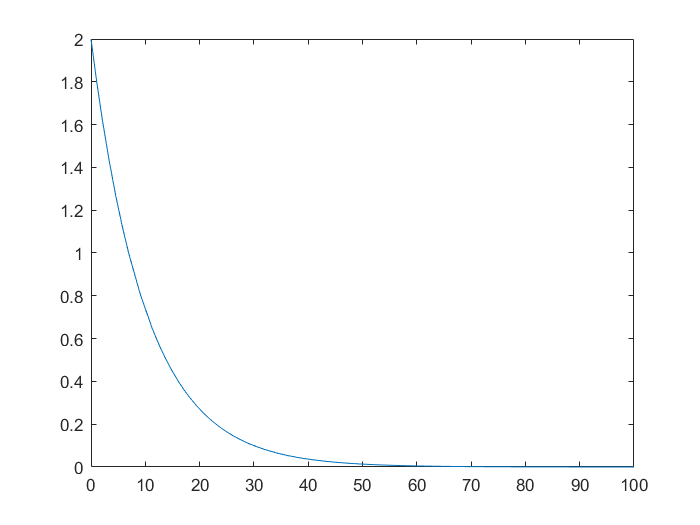

figure(1)
fplot(S.k, [0 100])

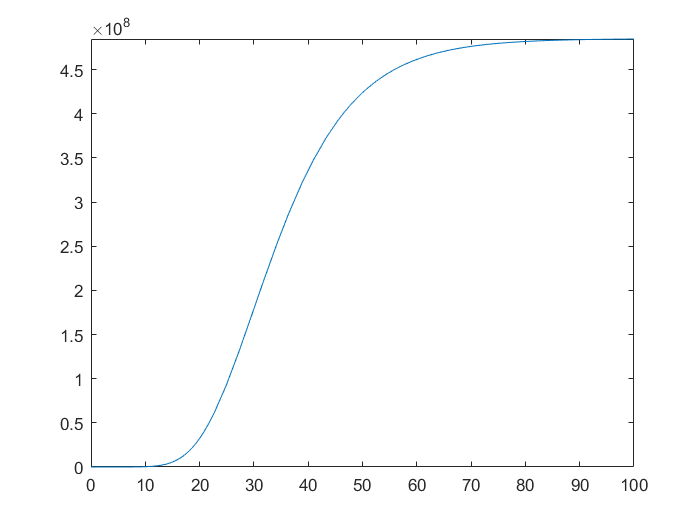


figure(2)
fplot(S.v, [0 100])

第二题的答案

time = solve(S.v - 2)

$$time = -10\,\log\left(1-\frac{\log\left(2\right)}{20}\right)$$

vpa(time)

$$ans = 0.35272172300235679459396992664341$$

第三题的答案

rate = diff(S.v)

$$rate = 2\,{\mathrm{e}}^{-\frac{t}{10}}\,{\mathrm{e}}^{20}\,{\mathrm{e}}^{-20\,{\mathrm{e}}^{-\frac{t}{10}}}$$

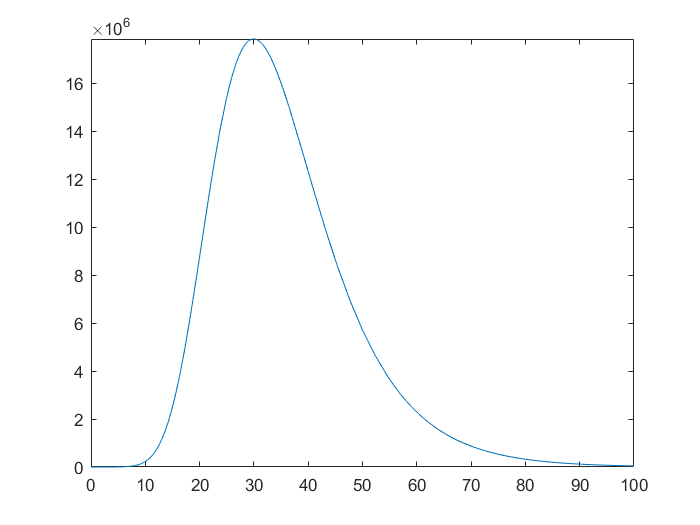

figure(3)
fplot(rate, [0 100])


time = solve(diff(rate))

$$time = 10\,\log\left(20\,{\mathrm{e}}^{20}\right)-200$$

vpa(time)

$$ans = 29.957322735539909934352235761425$$

第四题的答案